clc
clear

disp("Initilization Procedure")

Initilization Procedure


model.Parameters

disp("Calculate Operating Point")

Calculate Operating Point


for i=1:4
    [T_wOP, q_OP, alpha, omega_s_OP, omega_OP] = control.calculateOperatingPoint(param.ctrl.T_ref,i,param);
    param.ctrl.alpha(i) = alpha;
    param.ctrl.T_wOP(i) = T_wOP;
    param.ctrl.T_aOP(i) = 273.15+20;
    param.ctrl.omega_OP(i) = omega_OP;
    param.ctrl.omega_s_OP(i) = omega_s_OP;
    param.ctrl.q_OP(i) = q_OP;
    param.ctrl.xi_OP(3*(i-1)+1:3*i,1) = [T_wOP; param.ctrl.T_aOP(i); 0];
end
disp("calculate bilinear model matrices")

calculate bilinear model matrices


F = cell(1,param.n);
G = cell(1,param.n);
M = cell(1,param.n);
E =[]; % defines E to be empty
for i = 1:param.n
    F{i} = [-(param.thermo.B(i))/(param.thermo.C_w*param.thermo.rho_w*param.thermo.V_w(i)), (param.thermo.B(i))/(param.thermo.C_w*param.thermo.rho_w*param.thermo.V_w(i)), 0; 
             (param.thermo.B(i))/(param.thermo.C_a*param.thermo.rho_a*param.thermo.V_a(i)), -((param.ctrl.Q(i))/(param.thermo.V_a(i) + (param.thermo.B(i))/(param.thermo.C_a*param.thermo.rho_a*param.thermo.V_a(i)))), 0; 
             0, 1, 0,];
    G{i} = [param.thermo.T_c/param.thermo.V_w(i); 0; 0];
    M{i} = [-1/param.thermo.V_w(i), 0, 0; 0, 0, 0; 0, 0,0];
    E =[E; [0; (param.ctrl.Q(i)*param.thermo.T_A)/(param.thermo.V_a(i)); -param.ctrl.T_ref]];
end

param.model.F_cali = blkdiag(F{:});
param.model.G_cali = blkdiag(G{:});
param.model.M = M;
param.model.Epsilon = E;
%H(xi) is found as a function under +model as the function "H_xi.m"
disp("Calculate linearisation decoupled")

Calculate linearisation decoupled


ans =    -0.0250    0.0250         0         0         0         0         0         0         0         0         0         0
    2.9902   -0.7482         0         0         0         0         0         0         0         0         0         0
         0    1.0000         0         0         0         0         0         0         0         0         0         0
         0         0         0   -0.0251    0.0251         0         0         0         0         0         0         0
         0         0         0    3.0190   -0.6367         0         0         0         0         0         0         0
         0         0         0         0    1.0000         0         0         0         0         0         0         0
         0         0         0         0         0         0   -0.0250    0.0250         0         0         0         0
         0         0         0         0         0         0    2.9902   -0.5988         0         0         0         0
         0         0      

ans =    -0.0250         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0   -0.0251         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0   -0.0250         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0
         0         0      

param.model.A = param.model.F_cali+model.H_q(param.ctrl.q_OP,param);
param.model.B_Bar = param.model.G_cali+model.H_xi(param.ctrl.xi_OP,param);

%Linearisation for finding B is missing.    


disp("Calculate linearisation coupled")

Calculate linearisation coupled




disp("Testing controlability")

Testing controlability


Ta_ref_singularity= ((param.thermo.T_c*param.thermo.B+param.thermo.C_a*param.thermo.rho_a*param.ctrl.Q*param.thermo.T_A)./(param.thermo.B+param.thermo.C_a*param.thermo.rho_a*param.ctrl.Q));
if(isequal(round((param.ctrl.T_ref*ones(1,param.n)-Ta_ref_singularity),4),zeros(1,param.n)))
   error("The current selected refference causes a singularity chose another one")
end

disp("Testing T_ref")

Testing T_ref



if(param.ctrl.T_wOP < ones(1,param.n)*param.thermo.T_c)
    error("The choosen T_ref results in operationg point of the water outlet which is smaller then T_c, chose a higher T_ref")
end

% param.ctrl.ks(:,:,1) =[-0.0669, 0.3820, 0.0769];
% param.ctrl.ks(:,:,2) = [-0.0390, 0.2228, 0.0449];
% param.ctrl.ks(:,:,3) = [-0.0334, 0.1910, 0.0385];
% param.ctrl.ks(:,:,4) =[-0.0557,0.3184, 0.0641];

simtime = 10*60;

## Control

param.ctrl.Ks = control.DesignProcedure1(param);

Linear matrix variable 12x12 (symmetric, real, 24 variables)
Coefficient range: 1 to 1
Linear matrix variable 4x12 (full, real, 12 variables)
Coefficient range: 1 to 1
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                Constraint|     Coefficient range|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality 12x12|   0.024977 to 86.9567|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                Constraint|     Coefficient range|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality 12x12|   0.024977 to 86.9567|
|   #2|   Matrix inequality 12x12|                1 to 1|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++
 
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|          Constraint|   Primal residual|   Dual residual|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++

ans =   -0.5340 + 3.3908i
  -0.5340 - 3.3908i
  -0.3426 + 0.0000i
  -0.5276 + 3.4206i
  -0.5276 - 3.4206i
  -0.3429 + 0.0000i
  -0.5260 + 3.3948i
  -0.5260 - 3.3948i
  -0.3430 + 0.0000i
  -0.5319 + 3.3913i


Ks = Ks(:,:,1) =

    0.0282    0.1804    0.0621


Ks(:,:,2) =

    0.0191    0.1059    0.0365


Ks(:,:,3) =

    0.0172    0.0905    0.0311


Ks(:,:,4) =

    0.0247    0.1506    0.0519


ans =    -0.0500    0.0250         0         0         0         0         0         0         0         0         0         0
    2.9902   -0.7482         0         0         0         0         0         0         0         0         0         0
         0    1.0000         0         0         0         0         0         0         0         0         0         0
         0         0         0   -0.0501    0.0251         0         0         0         0         0         0         0
         0         0         0    3.0190   -0.6367         0         0         0         0         0         0         0
         0         0         0         0    1.0000         0         0         0         0         0         0         0
         0         0         0         0         0         0   -0.0500    0.0250         0         0         0         0
         0         0         0         0         0         0    2.9902   -0.5988         0         0         0         0
         0         0      

ans =   -21.7392         0         0         0
         0         0         0         0
         0         0         0         0
         0  -37.3132         0         0
         0         0         0         0
         0         0         0         0
         0         0  -43.4784         0
         0         0         0         0
         0         0         0         0
         0         0         0  -26.0417


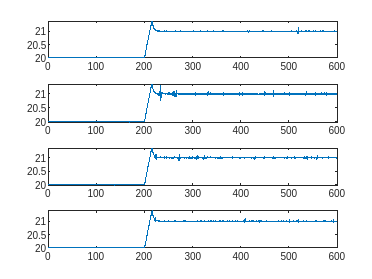

for i=1:4
    x0 = [param.ctrl.T_wOP(i); param.ctrl.T_aOP(i); 0];
    [t,x] = ode45(@(t,x)model.decoupledDynamics(t,x,i,param,200),[0 simtime],x0);
    decoupledResults(i).time = t;
    decoupledResults(i).Tw = x(:,1);
    decoupledResults(i).Ta = x(:,2);
    decoupledResults(i).T = x(:,3);
end
figure()
tiledlayout('vertical')
for i=1:4
    nexttile
    plot(decoupledResults(i).time,decoupledResults(i).Ta-273.15)
end

x0 = [param.ctrl.T_wOP.'; param.ctrl.T_aOP.'; zeros(4,1)];
options = odeset('RelTol',1e-8,'AbsTol',1e-10);
[t,x] = ode45(@(t,x)model.coupledDynamics(t,x,param,200),[0 simtime],x0,options);
coupledResults.time = t;
coupledResults.Tw = x(:,1:4);
coupledResults.Ta = x(:,5:8);
coupledResults.T = x(:,9:12);


figure()
tiledlayout('vertical')
for i=1:4
    nexttile
    plot(coupledResults.time,coupledResults.Ta(:,1)-273.15)
end